PROJETO - 1ºPARTE

- No ponto 1 recorremos a uma tabela para a estrutura de dados. Esta tabela contém colunas com as informações específicas dos ficheiros de áudio. O código percorre os ficheiros através de um ciclo for, extrai-mos o nome do ficheiro em partes de forma a obter o dígito e o número da repetição. Recorremos ao audioread de forma a carregar os áudio num array de valores. Os dados são inseridos na tabela T linha a linha e de seguida todos os dados são ordenados pela coluna "Repetição" para facilitar a organização. Decidimos colocar o numero de paciente fora do ciclo for, de forma a melhorar a eficiencia do codigo, pois este é o mesmo para todos os files audio.

folderPath = '/Users/louis/Documents/Engenharia Informática/2ºano/2ºSemestre/ATD/data/06';
files = dir(fullfile(folderPath, '*'));

filename = files(3).name;
participante = str2double(extractBetween(filename, '_', '_'));

T = table('Size', [0, 7], 'VariableTypes', {'string', 'string', 'double', 'double', 'double','cell','double'}, ...
          'VariableNames', {'Diretório', 'Nome_Ficheiro', 'Participante', 'Dígito', 'Repetição','Sinal','Taxa Amostragem'});

for i = 3:length(files)
    nome_ficheiro = files(i).name;
    diretorio = fullfile(folderPath, nome_ficheiro);
    parts = split(nome_ficheiro, '_');
    digito = str2double(parts{1});
    repeticao = str2double(extractBefore(parts{end}, '.'));
    [sinal, taxa] = audioread(diretorio);

    newRow = {diretorio, nome_ficheiro, participante, digito, repeticao,sinal,taxa};
    T = [T; newRow];
end
T = sortrows(T,"Repetição");
disp(T);

                                           Diretório                                            Nome_Ficheiro    Participante    Dígito    Repetição         Sinal          Taxa Amostragem
    ________________________________________________________________________________________    _____________    ____________    ______    _________    ________________    _______________

    "/Users/louis/Documents/Engenharia Informática/2ºano/2ºSemestre/ATD/data/06/0_06_0.wav"     "0_06_0.wav"          6            0           0        {31228×1 double}         48000     
    "/Users/louis/Documents/Engenharia Informática/2ºano/2ºSemestre/ATD/data/06/1_06_0.wav"     "1_06_0.wav"          6            1           0        {26423×1 double}         48000     
    "/Use

- No ponto 3 percorremos a tabela de forma a obter o sinal e os seus dados tal como a taxa, a amplitude e o tempo. E de seguida chama-mos uma função que nos permitirá visualizar as ondas de amplitude de cada áudio em função do tempo. Utilizamos uma programação dinâmica ao criar a lista digitos_plotados_original pois assim o codigo if não correrá deforma a melhorar a performance do código, caso esse dígito já tenha sido plotado.

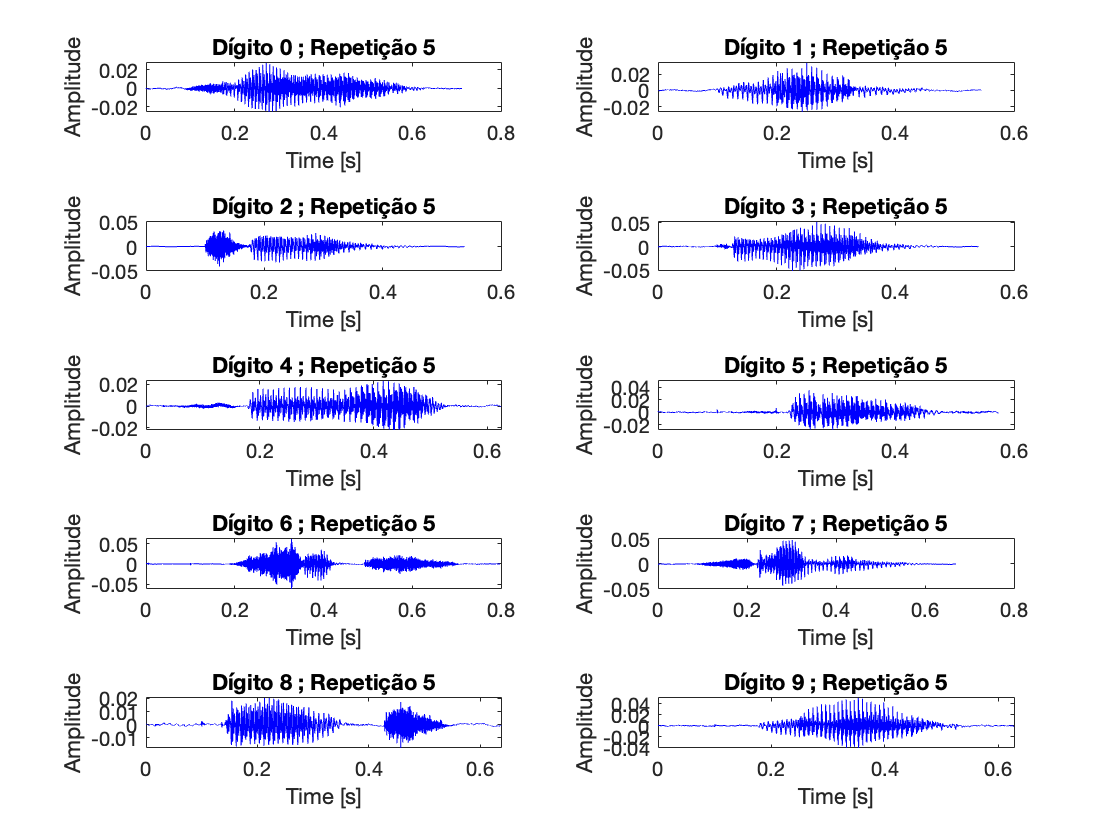

figure;
tiledlayout(5,2);
digitos_plotados_original = [];

for i = 1:height(T)
    digito = T.("Dígito")(i);
    sinal = (T.("Sinal"){i});
    taxa = T.("Taxa Amostragem")(i);
    t = (0:length(sinal)-1) / taxa;
    
    visualizar_digito(t,sinal,digito,digitos_plotados_original,T.("Repetição")(i))
end

- Para melhorar a diferenciação entre dígitos, começamos pela normalização do áudio, descobrindo o máximo valor da amplitude e dividindo todos os valores de audio pelo mesmo. Após isto, optamos na utilização da função de energia para encontrar os indices finais e iniciais de som para cortar partes desnecessárias do audio isolando apenas na pronunciação do digíto. de seguida de forma a colocar-mos todos com o mesmo intrevalo de tempo, percorremos a tabela de sinal obtivemos o maior indice. Por fim como pedido no ponto 5 visualizamos os digitos utilizando a mesma função do ponto 3.

- Como pedido no ponto 6 foi possível observar uma diferença na amplitude devido à normalização, neste no gráfico no exercício 5 apresenta uma amplitude mais nivelada. O silêncio inicial e final inicializou a pronúncia do dígito mais cedo, porém poderá haver um mínimo corte no áudio devido ao cálculo dos intervalos para o ajuste.  A visualização dos gráficos tornou-se mais simples devido ao acrescento de silêncio no final dos áudios de forma a tornar o tempo dos mesmos iguais.

- No ponto 7, dentro do ciclo que percorre a tabela, para cada sinal de áudio, fomos calcular a amplitude mínima e máxima. A energia total, através da soma dos quadrados das amplitudes do sinal. A média de amplitude, a partir da média dos valores absolutos do sinal e por fim a variância da amplitude, que mede a dispersão dos valores da amplitude em torno da média. De seguida cada valor calculado é armazenado numa lista própria na posição correspondente ao dígito. Para o ponto 8, recorremos à função graficos(lista,label) damos plot nos gráficos, cada ponto no gráfico corresponde a um valor extraido de um áudio específico.

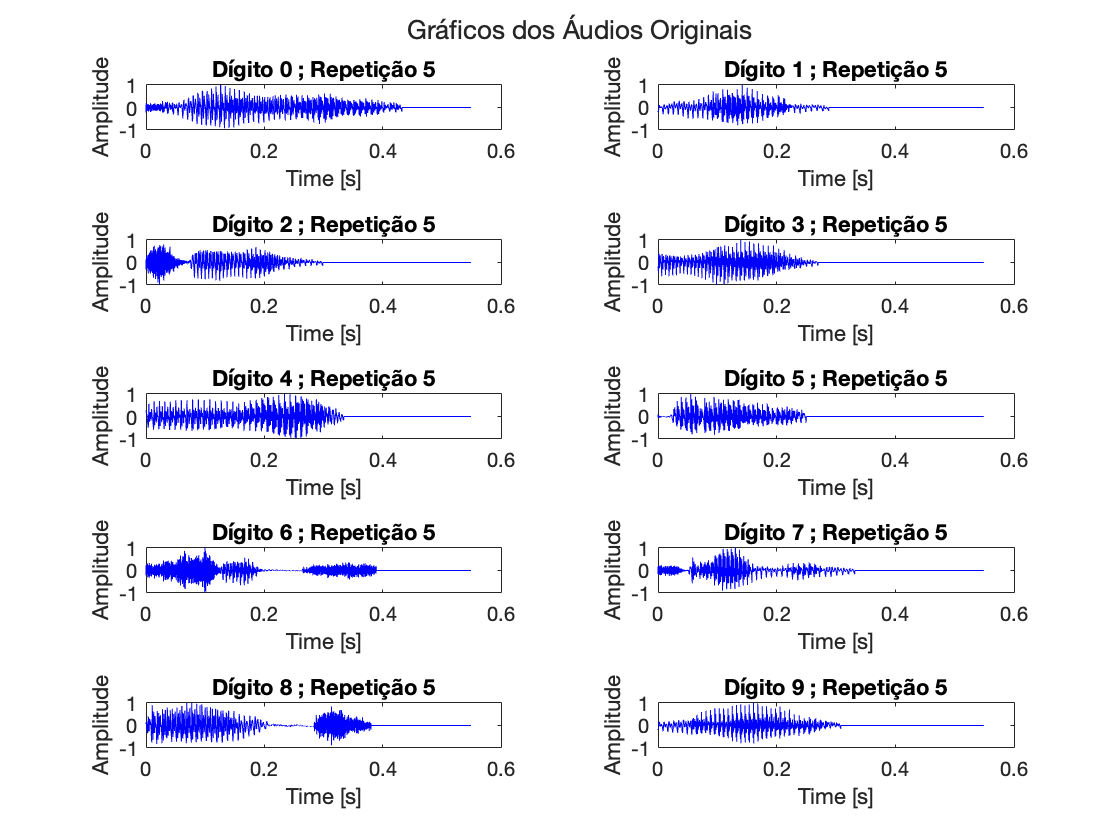

  
figure;
tiledlayout(5,2);
digitos_plotados = [];

lista_maximo = cell(1, 10);
lista_minimo = cell(1, 10);
lista_energia_total = cell(1, 10);
lista_media_amplitude = cell(1, 10);
lista_variancia = cell(1, 10);

for i = 1:height(T)
    digito = T.("Dígito")(i);
        
    sinal = (T.("Sinal"){i});
    maxsinal = max(abs(sinal));
    sinal = sinal/maxsinal;
    taxa = T.("Taxa Amostragem")(i);  

    limiar = 0.1;        
    
    indice_inicio = somatorio(sinal,limiar,0);
    %M = movsum(A,3)
    indice_fim = somatorio(sinal,limiar,length(sinal));
    %max_size = encontrar_maior_sinal(T);
    
    sinal = sinal(indice_inicio:indice_fim);
    %sinal(end+1:max_size) = 0;
    sinal(end+1:26358) = 0;
    t = (0:length(sinal)-1) / taxa;
    
    visualizar_digito(t,sinal,digito,digitos_plotados,T.("Repetição")(i))
    
    energia = 0;
    var = 0;
    media_amplitude = sum(abs(sinal))/length(sinal);
    
    for j = 1:length(sinal)
        var = var + (abs(sinal(j)) - media_amplitude)^2;
        energia = sinal(j)^2 + energia;
    end
    
    var = sqrt(var/(length(sinal)-1));
    minimo = abs(sinal);
    
    lista_maximo{digito + 1} = [lista_maximo{digito + 1}, maxsinal]; 
    
    lista_minimo{digito + 1} = [lista_minimo{digito + 1}, min(minimo(minimo>0))];
    
    lista_energia_total{digito + 1} = [lista_energia_total{digito + 1}, energia];
    
    lista_media_amplitude{digito + 1} = [lista_media_amplitude{digito + 1}, media_amplitude];
   
    lista_variancia{digito + 1} = [lista_variancia{digito + 1}, var];
end

sgtitle('Gráficos dos Áudios Originais');

FAZER O EXEMPLO DO CROSSING RATE QUANTAS VEZES O SINAL PASSA NO ZERO

TEMPO ATÉ AO PICO MAXIMO

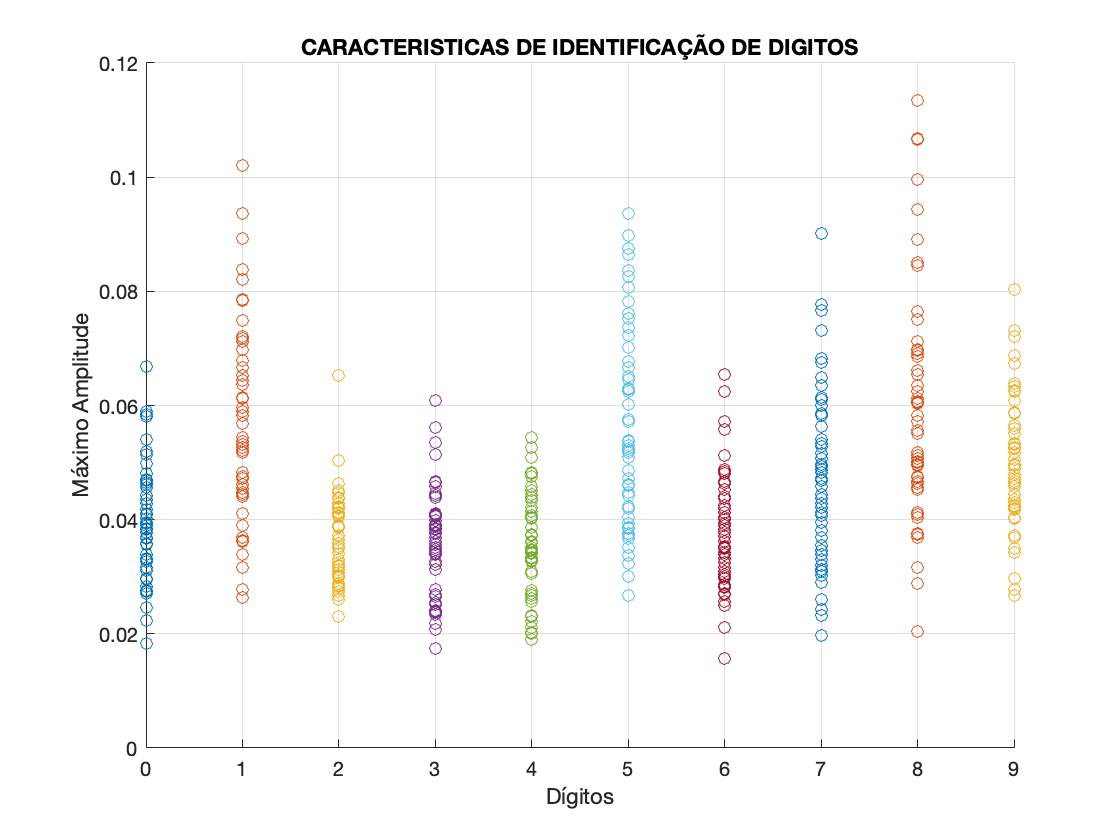


graficos(lista_maximo,'Máximo Amplitude')

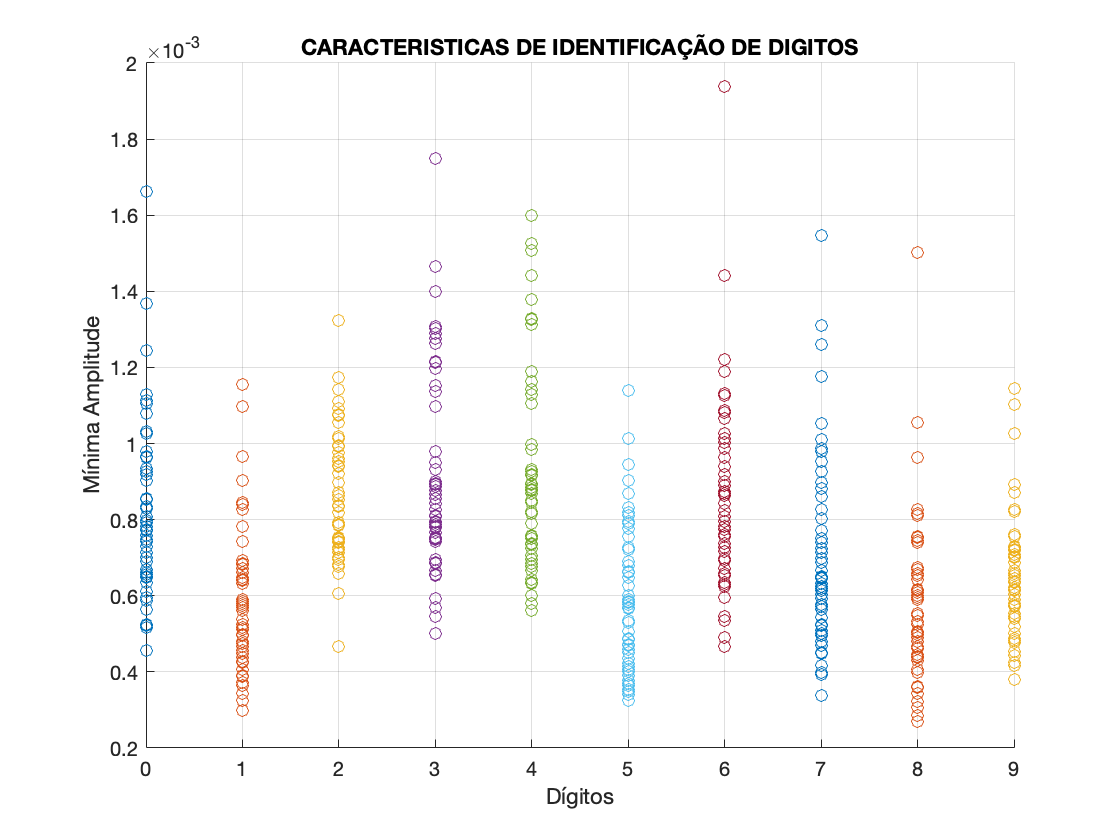

graficos(lista_minimo,'Mínima Amplitude')

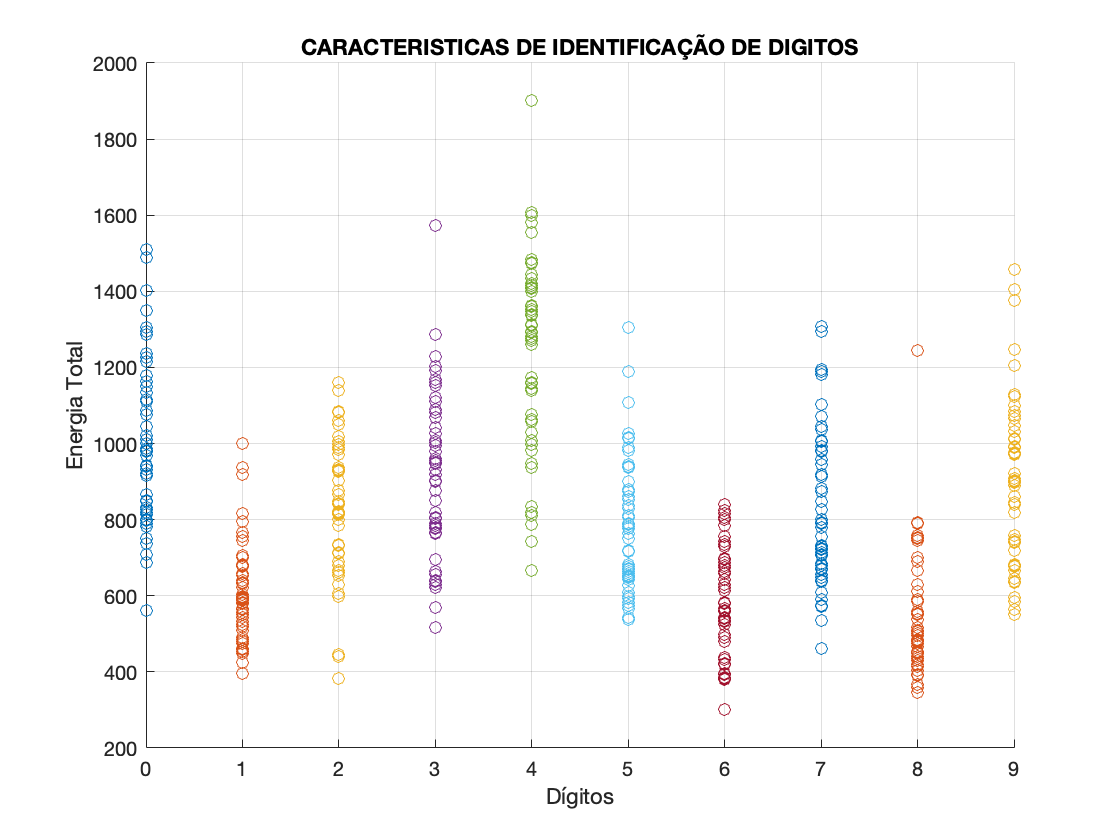

graficos(lista_energia_total,'Energia Total')

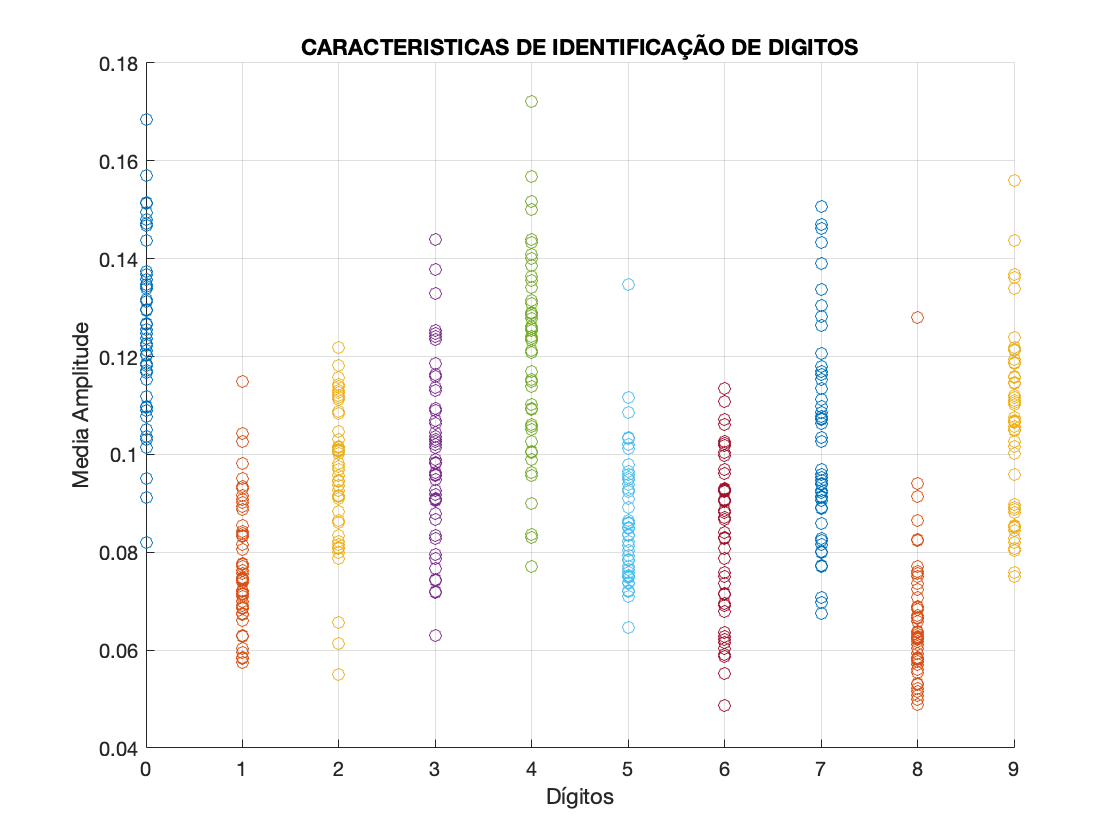

graficos(lista_media_amplitude,'Media Amplitude')

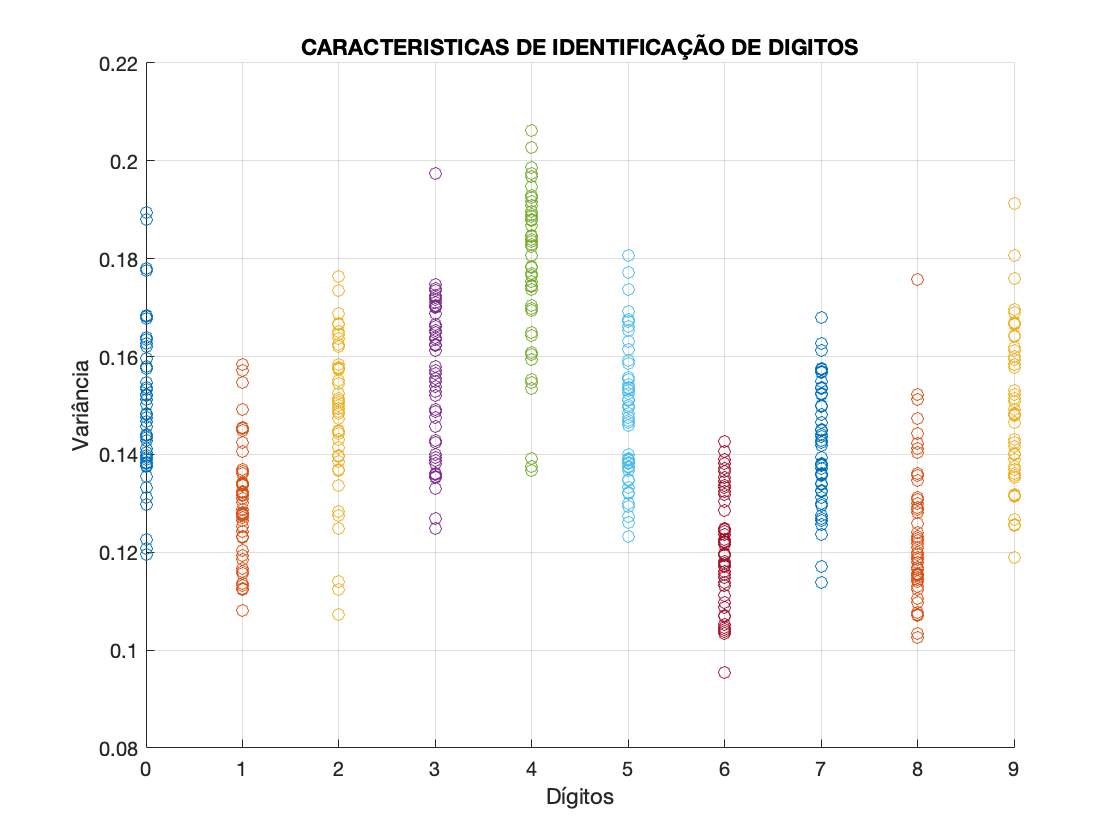

graficos(lista_variancia,'Variância')


T_final = removevars(T,["Sinal"]);
save('projeto.mat', 'T_final')


- No ponto 9, removemos da tabela os dados "Sinal", e guardamos num ficheiro .mat.

function index = somatorio(sinal,limiar,size)
    energia = 0;
    index = 5;
    for i = 1:length(sinal)
        energia = sinal(abs(size-i))^2 + energia;
        if(i == index)
            index = index + 5;
            if( energia > limiar)
                index = abs(size-i);
                return
            end
            energia = 0;
        end
    end
end

function max_tamanho = encontrar_maior_sinal(T)
    max_tamanho = 0; % Inicializa a variável para armazenar o maior tamanho

    for i = 1:height(T)
        tamanho_sinal = length(T.("Sinal"){i}); % Obtém o tamanho do sinal na linha i
        if tamanho_sinal > max_tamanho
            max_tamanho = tamanho_sinal; % Atualiza o maior tamanho encontrado
        end
    end
end


function graficos(lista,label)

    figure;
    hold on;
    for d = 1:10
        if ~isempty(lista{d})
            
            plot(repmat(d-1, 1, length(lista{d})), lista{d}, 'o');
        end
    end
    xlabel('Dígitos');
    ylabel(label);
    title('CARACTERISTICAS DE IDENTIFICAÇÃO DE DIGITOS');
    grid on;
    hold off;
end


function visualizar_digito(t,sinal,digito,digitos_plotados,repeticao)

    if ~ismember(digito, digitos_plotados) && repeticao == 5
        nexttile;
        
        plot(t, sinal, 'b');  
        xlabel('Time [s]'); ylabel('Amplitude');
        
        title(sprintf('Dígito %d ; Repetição %d', digito, repeticao)); 
        
        digitos_plotados = [digitos_plotados, digito];
    end
end